%calculating the mean first passage time analytically/numerically 
%to investigate effect of branch migration domain length on DNA/RNA TMSD

%b = 20 %define branch migration domain length
g = 6 %define invader toehold length

g = 6


R = 1.987/1000 %universal gas constant in kcal/K/mol 

R = 0.0020

temp = 298.15 %temperature in K

temp = 298.1500

%free energy parameters
dGassoc = 2.6*R*temp

dGassoc = 1.5403

dGbp = -2.52*R*temp

dGbp = -1.4929

dGp = 3.6*R*temp

dGp = 2.1327

dGrd = -0.7*R*temp

dGrd = -0.4147

dGbm = 7.4*R*temp 

dGbm = 4.3839

%absolute rate constant
k_bp = 5.4*10^7

k_bp = 54000000

k_eff = zeros(1,30)

k_eff =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time = zeros(1, 30)

first_pass_time =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


prob_unbound = zeros(1, 30)

prob_unbound =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0



%loop through branch migration domain lengths 
for b = 10:40

    %define forward and reverse transition rates
    k_AA = 0;
    k_AB1 = k_bp * exp(-dGassoc/(R*temp)) * (5*10^-8)
    k_B1A = k_bp * exp(dGbp/(R*temp))
    k_BC1ij = k_bp;
    k_BC1ji = k_bp * exp(dGbp/(R*temp));
    k_C1f = k_bp * exp(-(dGbm + dGp - dGrd)/(R*temp))
    k_Cf = k_bp * exp(-(dGbm - dGrd)/(R*temp))
    k_Cr = k_bp * exp(-dGbm/(R*temp));
    k_CD = k_bp * exp(-(dGbm - dGrd)/(R*temp));
    k_DC = 0 
    k_DD = 1
    
    %create arrays of forward and reverse transition rates
    if g == 1
        Kf = [k_DD, k_CD, repmat(k_Cf, [1, b-2]), k_C1f, k_AB1]
        Kb = [k_DC, repmat(k_Cr, [1, b-2]), k_Cr, k_B1A, k_AA]
        
    else
        Kf = [k_DD, k_CD, repmat(k_Cf, [1, b-2]), k_C1f, repmat(k_BC1ij, [1, g-2]), k_BC1ij, k_AB1]
        Kb = [k_DC, repmat(k_Cr, [1, b-2]), k_Cr, k_BC1ji, repmat(k_BC1ji, [1, g-2]), k_B1A, k_AA]
    end
    
    Pn_j0 = zeros(1,numel(Kf))
    Pn_j0 (1) = 0
    %calculate flux between each state
    for Pn = 2:numel(Kf)
        Pn_j0(Pn)  = 1/Kf(Pn) + Kb(Pn-1)/Kf(Pn)*Pn_j0(Pn-1)
    end

    first_pass_time (b-9) = sum(Pn_j0) %calculate first passage time
    k_eff (b-9) = 1/(first_pass_time (b-9)*(5*10^-8)) %calculate effective rate constant
    prob_unbound(b-9) = Pn_j0(end)/sum(Pn_j0) %calculate probability of being in unbound state
end

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 447.8662

k_Cf = 1.6391e+04

k_DC = 0

k_DD = 1

Kf = 	1.0e+07 *

    0.0000    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb = 	1.0e+06 *

         0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448         0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 = 	1.0e+-4 *

         0    0.6101         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 = 	1.0e+-3 *

         0    0.0610    0.1839         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 = 	1.0e+-3 *

         0    0.0610    0.1839    0.4313         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 = 	1.0e+-3 *

         0    0.0610    0.1839    0.4313    0.9295         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    2.4132         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    2.4132    0.1942         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    2.4132    0.1942    0.0156         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    2.4132    0.1942    0.0156    0.0013         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    2.4132    0.1942    0.0156    0.0013    0.0001         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    2.4132    0.1942    0.0156    0.0013    0.0001    0.0000         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    2.4132    0.1942    0.0156    0.0013    0.0001    0.0000  181.7211


first_pass_time =   184.4098         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff = 	1.0e+05 *

    1.0845         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.9854         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 447.8662

k_Cf = 1.6391e+04

k_DC = 0

k_DD = 1

Kf = 	1.0e+07 *

    0.0000    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb = 	1.0e+06 *

         0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448         0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 = 	1.0e+-4 *

         0    0.6101         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 = 	1.0e+-3 *

         0    0.0610    0.1839         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 = 	1.0e+-3 *

         0    0.0610    0.1839    0.4313         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 = 	1.0e+-3 *

         0    0.0610    0.1839    0.4313    0.9295         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    4.8617         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    4.8617    0.3912         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    4.8617    0.3912    0.0315         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    4.8617    0.3912    0.0315    0.0025         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    4.8617    0.3912    0.0315    0.0025    0.0002         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    4.8617    0.3912    0.0315    0.0025    0.0002    0.0000         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    4.8617    0.3912    0.0315    0.0025    0.0002    0.0000  360.6070


first_pass_time =   184.4098  366.0245         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff = 	1.0e+05 *

    1.0845    0.5464         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.9854    0.9852         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 447.8662

k_Cf = 1.6391e+04

k_DC = 0

k_DD = 1

Kf = 	1.0e+07 *

    0.0000    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448         0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =          0    0.6101         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0610    0.1839         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0610    0.1839    0.4313         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0610    0.1839    0.4313    0.9295         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    9.7925         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    9.7925    0.7879         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    9.7925    0.7879    0.0634         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    9.7925    0.7879    0.0634    0.0051         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    9.7925    0.7879    0.0634    0.0051    0.0004         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    9.7925    0.7879    0.0634    0.0051    0.0004    0.0000         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    9.7925    0.7879    0.0634    0.0051    0.0004    0.0000  720.8390


first_pass_time =   184.4098  366.0245  731.7516         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff =     1.0845    0.5464    0.2733         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.9854    0.9852    0.9851         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 447.8662

k_Cf = 1.6391e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448         0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =          0    0.6101         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0610    0.1839         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0610    0.1839    0.4313         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0610    0.1839    0.4313    0.9295         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676   19.7220         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676   19.7220    1.5868         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676   19.7220    1.5868    0.1277         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676   19.7220    1.5868    0.1277    0.0103         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676   19.7220    1.5868    0.1277    0.0103    0.0008         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676   19.7220    1.5868    0.1277    0.0103    0.0008    0.0001         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0003    0.0197    0.0016    0.0001    0.0000    0.0000    0.0000    1.4463


first_pass_time =     0.1844    0.3660    0.7318    1.4682         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff =     1.0845    0.5464    0.2733    0.1362         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.9854    0.9852    0.9851    0.9850         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 447.8662

k_Cf = 1.6391e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448         0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =          0    0.6101         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0610    0.1839         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0610    0.1839    0.4313         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0610    0.1839    0.4313    0.9295         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389   39.7175         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389   39.7175    3.1957         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389   39.7175    3.1957    0.2571         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389   39.7175    3.1957    0.2571    0.0207         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389   39.7175    3.1957    0.2571    0.0207    0.0017         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389   39.7175    3.1957    0.2571    0.0207    0.0017    0.0001         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0003    0.0005    0.0397    0.0032    0.0003    0.0000    0.0000    0.0000    2.9071


first_pass_time =     0.1844    0.3660    0.7318    1.4682    2.9513         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff =     1.0845    0.5464    0.2733    0.1362    0.0678         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.9854    0.9852    0.9851    0.9850    0.9850         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 447.8662

k_Cf = 1.6391e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448         0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =          0    0.6101         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0610    0.1839         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0610    0.1839    0.4313         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0610    0.1839    0.4313    0.9295         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852   79.9834         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852   79.9834    6.4354         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852   79.9834    6.4354    0.5178         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852   79.9834    6.4354    0.5178    0.0417         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852   79.9834    6.4354    0.5178    0.0417    0.0034         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852   79.9834    6.4354    0.5178    0.0417    0.0034    0.0003         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0003    0.0005    0.0011    0.0800    0.0064    0.0005    0.0000    0.0000    0.0000    5.8488


first_pass_time =     0.1844    0.3660    0.7318    1.4682    2.9513    5.9379         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff =     1.0845    0.5464    0.2733    0.1362    0.0678    0.0337         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.9854    0.9852    0.9851    0.9850    0.9850    0.9850         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 447.8662

k_Cf = 1.6391e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448         0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =          0    0.6101         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0610    0.1839         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0610    0.1839    0.4313         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0610    0.1839    0.4313    0.9295         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854  161.0690         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854  161.0690   12.9595         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854  161.0690   12.9595    1.0427         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854  161.0690   12.9595    1.0427    0.0839         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854  161.0690   12.9595    1.0427    0.0839    0.0068         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854  161.0690   12.9595    1.0427    0.0839    0.0068    0.0005         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0161    0.0013    0.0001    0.0000    0.0000    0.0000    1.1773


first_pass_time =     0.0184    0.0366    0.0732    0.1468    0.2951    0.5938    1.1952         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff =     1.0845    0.5464    0.2733    0.1362    0.0678    0.0337    0.0167         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.9854    0.9852    0.9851    0.9850    0.9850    0.9850    0.9850         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 447.8662

k_Cf = 1.6391e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448         0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =          0    0.6101         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0610    0.1839         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0610    0.1839    0.4313         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0610    0.1839    0.4313    0.9295         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010  324.3553         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010  324.3553   26.0975         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010  324.3553   26.0975    2.0998         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010  324.3553   26.0975    2.0998    0.1689         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010  324.3553   26.0975    2.0998    0.1689    0.0136         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010  324.3553   26.0975    2.0998    0.1689    0.0136    0.0011         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0324    0.0026    0.0002    0.0000    0.0000    0.0000    2.3702


first_pass_time =     0.0184    0.0366    0.0732    0.1468    0.2951    0.5938    1.1952    2.4063         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff =     1.0845    0.5464    0.2733    0.1362    0.0678    0.0337    0.0167    0.0083         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.9854    0.9852    0.9851    0.9850    0.9850    0.9850    0.9850    0.9850         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 447.8662

k_Cf = 1.6391e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448         0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =          0    0.6101         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0610    0.1839         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0610    0.1839    0.4313         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0610    0.1839    0.4313    0.9295         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010    8.8626         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010    8.8626  653.1737         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010    8.8626  653.1737   52.5541         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010    8.8626  653.1737   52.5541    4.2285         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010    8.8626  653.1737   52.5541    4.2285    0.3402         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010    8.8626  653.1737   52.5541    4.2285    0.3402    0.0274         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010    8.8626  653.1737   52.5541    4.2285    0.3402    0.0274    0.0022         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0653    0.0053    0.0004    0.0000    0.0000    0.0000    4.7724


first_pass_time =     0.0184    0.0366    0.0732    0.1468    0.2951    0.5938    1.1952    2.4063    4.8452         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff =     1.0845    0.5464    0.2733    0.1362    0.0678    0.0337    0.0167    0.0083    0.0041         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.9854    0.9852    0.9851    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 447.8662

k_Cf = 1.6391e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448         0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =          0    0.6101         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0610    0.1839         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0610    0.1839    0.4313         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0610    0.1839    0.4313    0.9295         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010    8.8626         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010    8.8626   17.8471         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0003    0.0005    0.0011    0.0022    0.0044    0.0089    0.0178    1.3153         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0003    0.0005    0.0011    0.0022    0.0044    0.0089    0.0178    1.3153    0.1058         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0003    0.0005    0.0011    0.0022    0.0044    0.0089    0.0178    1.3153    0.1058    0.0085         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0003    0.0005    0.0011    0.0022    0.0044    0.0089    0.0178    1.3153    0.1058    0.0085    0.0007         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0003    0.0005    0.0011    0.0022    0.0044    0.0089    0.0178    1.3153    0.1058    0.0085    0.0007    0.0001         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0003    0.0005    0.0011    0.0022    0.0044    0.0089    0.0178    1.3153    0.1058    0.0085    0.0007    0.0001    0.0000         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.1315    0.0106    0.0009    0.0001    0.0000    0.0000    9.6100


first_pass_time =     0.0184    0.0366    0.0732    0.1468    0.2951    0.5938    1.1952    2.4063    4.8452    9.7566         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff =     1.0845    0.5464    0.2733    0.1362    0.0678    0.0337    0.0167    0.0083    0.0041    0.0020         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.9854    0.9852    0.9851    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 447.8662

k_Cf = 1.6391e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448         0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =          0    0.6101         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0610    0.1839         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0610    0.1839    0.4313         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0610    0.1839    0.4313    0.9295         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010    8.8626         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010    8.8626   17.8471         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010    8.8626   17.8471   35.9398         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0003    0.0005    0.0011    0.0022    0.0044    0.0089    0.0178    0.0359    2.6488         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0003    0.0005    0.0011    0.0022    0.0044    0.0089    0.0178    0.0359    2.6488    0.2131         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0003    0.0005    0.0011    0.0022    0.0044    0.0089    0.0178    0.0359    2.6488    0.2131    0.0171         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0003    0.0005    0.0011    0.0022    0.0044    0.0089    0.0178    0.0359    2.6488    0.2131    0.0171    0.0014         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0003    0.0005    0.0011    0.0022    0.0044    0.0089    0.0178    0.0359    2.6488    0.2131    0.0171    0.0014    0.0001         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0003    0.0005    0.0011    0.0022    0.0044    0.0089    0.0178    0.0359    2.6488    0.2131    0.0171    0.0014    0.0001    0.0000         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0265    0.0021    0.0002    0.0000    0.0000    0.0000    1.9352


first_pass_time =     0.0018    0.0037    0.0073    0.0147    0.0295    0.0594    0.1195    0.2406    0.4845    0.9757    1.9647         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff =     1.0845    0.5464    0.2733    0.1362    0.0678    0.0337    0.0167    0.0083    0.0041    0.0020    0.0010         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.9854    0.9852    0.9851    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 447.8662

k_Cf = 1.6391e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448         0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =          0    0.6101         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0610    0.1839         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0610    0.1839    0.4313         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0610    0.1839    0.4313    0.9295         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010    8.8626         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010    8.8626   17.8471         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010    8.8626   17.8471   35.9398         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010    8.8626   17.8471   35.9398   72.3739         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0003    0.0005    0.0011    0.0022    0.0044    0.0089    0.0178    0.0359    0.0724    5.3339         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0003    0.0005    0.0011    0.0022    0.0044    0.0089    0.0178    0.0359    0.0724    5.3339    0.4292         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0003    0.0005    0.0011    0.0022    0.0044    0.0089    0.0178    0.0359    0.0724    5.3339    0.4292    0.0345         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0003    0.0005    0.0011    0.0022    0.0044    0.0089    0.0178    0.0359    0.0724    5.3339    0.4292    0.0345    0.0028         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0003    0.0005    0.0011    0.0022    0.0044    0.0089    0.0178    0.0359    0.0724    5.3339    0.4292    0.0345    0.0028    0.0002         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0003    0.0005    0.0011    0.0022    0.0044    0.0089    0.0178    0.0359    0.0724    5.3339    0.4292    0.0345    0.0028    0.0002    0.0000         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0007    0.0533    0.0043    0.0003    0.0000    0.0000    0.0000    3.8969


first_pass_time =     0.0018    0.0037    0.0073    0.0147    0.0295    0.0594    0.1195    0.2406    0.4845    0.9757    1.9647    3.9563         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff =     1.0845    0.5464    0.2733    0.1362    0.0678    0.0337    0.0167    0.0083    0.0041    0.0020    0.0010    0.0005         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.9854    0.9852    0.9851    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 447.8662

k_Cf = 1.6391e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448         0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =          0    0.6101         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0610    0.1839         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0610    0.1839    0.4313         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0610    0.1839    0.4313    0.9295         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010    8.8626         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010    8.8626   17.8471         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010    8.8626   17.8471   35.9398         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010    8.8626   17.8471   35.9398   72.3739         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010    8.8626   17.8471   35.9398   72.3739  145.7432         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    1.0741         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    1.0741    0.0864         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    1.0741    0.0864    0.0070         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    1.0741    0.0864    0.0070    0.0006         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    1.0741    0.0864    0.0070    0.0006    0.0000         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    1.0741    0.0864    0.0070    0.0006    0.0000    0.0000         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0007    0.0015    0.1074    0.0086    0.0007    0.0001    0.0000    0.0000    7.8473


first_pass_time =     0.0018    0.0037    0.0073    0.0147    0.0295    0.0594    0.1195    0.2406    0.4845    0.9757    1.9647    3.9563    7.9670         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff =     1.0845    0.5464    0.2733    0.1362    0.0678    0.0337    0.0167    0.0083    0.0041    0.0020    0.0010    0.0005    0.0003         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.9854    0.9852    0.9851    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 447.8662

k_Cf = 1.6391e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448         0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =          0    0.6101         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0610    0.1839         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0610    0.1839    0.4313         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0610    0.1839    0.4313    0.9295         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010    8.8626         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010    8.8626   17.8471         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010    8.8626   17.8471   35.9398         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010    8.8626   17.8471   35.9398   72.3739         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010    8.8626   17.8471   35.9398   72.3739  145.7432         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010    8.8626   17.8471   35.9398   72.3739  145.7432  293.4908         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    2.1630         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    2.1630    0.1740         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    2.1630    0.1740    0.0140         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    2.1630    0.1740    0.0140    0.0011         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    2.1630    0.1740    0.0140    0.0011    0.0001         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    2.1630    0.1740    0.0140    0.0011    0.0001    0.0000         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0003    0.0216    0.0017    0.0001    0.0000    0.0000    0.0000    1.5802


first_pass_time =     0.0002    0.0004    0.0007    0.0015    0.0030    0.0059    0.0120    0.0241    0.0485    0.0976    0.1965    0.3956    0.7967    1.6044         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff =     1.0845    0.5464    0.2733    0.1362    0.0678    0.0337    0.0167    0.0083    0.0041    0.0020    0.0010    0.0005    0.0003    0.0001         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.9854    0.9852    0.9851    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 447.8662

k_Cf = 1.6391e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0000    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =          0    0.6101         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0610    0.1839         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0610    0.1839    0.4313         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0610    0.1839    0.4313    0.9295         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010    8.8626         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010    8.8626   17.8471         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010    8.8626   17.8471   35.9398         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010    8.8626   17.8471   35.9398   72.3739         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010    8.8626   17.8471   35.9398   72.3739  145.7432         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010    8.8626   17.8471   35.9398   72.3739  145.7432  293.4908         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010    8.8626   17.8471   35.9398   72.3739  145.7432  293.4908  591.0179         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    4.3558         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    4.3558    0.3505         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    4.3558    0.3505    0.0282         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    4.3558    0.3505    0.0282    0.0023         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    4.3558    0.3505    0.0282    0.0023    0.0002         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    4.3558    0.3505    0.0282    0.0023    0.0002    0.0000


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    4.3558    0.3505    0.0282    0.0023    0.0002    0.0000


first_pass_time =     0.0002    0.0004    0.0007    0.0015    0.0030    0.0059    0.0120    0.0241    0.0485    0.0976    0.1965    0.3956    0.7967    1.6044    3.2308         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff =     1.0845    0.5464    0.2733    0.1362    0.0678    0.0337    0.0167    0.0083    0.0041    0.0020    0.0010    0.0005    0.0003    0.0001    0.0001         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.9854    0.9852    0.9851    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 447.8662

k_Cf = 1.6391e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0000    5.4000    5.4000    5.4000    5.4000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448    4.3448


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =          0    0.6101         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0610    0.1839         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0610    0.1839    0.4313         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0610    0.1839    0.4313    0.9295         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010    8.8626         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010    8.8626   17.8471         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010    8.8626   17.8471   35.9398         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010    8.8626   17.8471   35.9398   72.3739         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010    8.8626   17.8471   35.9398   72.3739  145.7432         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010    8.8626   17.8471   35.9398   72.3739  145.7432  293.4908         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010    8.8626   17.8471   35.9398   72.3739  145.7432  293.4908  591.0179         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0003    0.0005    0.0011    0.0022    0.0044    0.0089    0.0178    0.0359    0.0724    0.1457    0.2935    0.5910    1.1902         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    8.7715         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    8.7715    0.7058         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    8.7715    0.7058    0.0568         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    8.7715    0.7058    0.0568    0.0046         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    8.7715    0.7058    0.0568    0.0046    0.0004


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    8.7715    0.7058    0.0568    0.0046    0.0004


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    8.7715    0.7058    0.0568    0.0046    0.0004


first_pass_time =     0.0002    0.0004    0.0007    0.0015    0.0030    0.0059    0.0120    0.0241    0.0485    0.0976    0.1965    0.3956    0.7967    1.6044    3.2308    6.5060         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff =     1.0845    0.5464    0.2733    0.1362    0.0678    0.0337    0.0167    0.0083    0.0041    0.0020    0.0010    0.0005    0.0003    0.0001    0.0001    0.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.9854    0.9852    0.9851    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 447.8662

k_Cf = 1.6391e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0000    5.4000    5.4000    5.4000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =          0    0.6101         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0610    0.1839         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0610    0.1839    0.4313         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0610    0.1839    0.4313    0.9295         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010    8.8626         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010    8.8626   17.8471         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010    8.8626   17.8471   35.9398         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010    8.8626   17.8471   35.9398   72.3739         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010    8.8626   17.8471   35.9398   72.3739  145.7432         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010    8.8626   17.8471   35.9398   72.3739  145.7432  293.4908         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010    8.8626   17.8471   35.9398   72.3739  145.7432  293.4908  591.0179         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0003    0.0005    0.0011    0.0022    0.0044    0.0089    0.0178    0.0359    0.0724    0.1457    0.2935    0.5910    1.1902         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0003    0.0005    0.0011    0.0022    0.0044    0.0089    0.0178    0.0359    0.0724    0.1457    0.2935    0.5910    1.1902    2.3967         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0007    0.0015    0.0029    0.0059    0.0119    0.0240    1.7664         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0007    0.0015    0.0029    0.0059    0.0119    0.0240    1.7664    0.1421         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0007    0.0015    0.0029    0.0059    0.0119    0.0240    1.7664    0.1421    0.0114         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0007    0.0015    0.0029    0.0059    0.0119    0.0240    1.7664    0.1421    0.0114    0.0009


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0007    0.0015    0.0029    0.0059    0.0119    0.0240    1.7664    0.1421    0.0114    0.0009


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0007    0.0015    0.0029    0.0059    0.0119    0.0240    1.7664    0.1421    0.0114    0.0009


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0007    0.0015    0.0029    0.0059    0.0119    0.0240    1.7664    0.1421    0.0114    0.0009


first_pass_time =     0.0000    0.0000    0.0001    0.0001    0.0003    0.0006    0.0012    0.0024    0.0048    0.0098    0.0196    0.0396    0.0797    0.1604    0.3231    0.6506    1.3101         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff =     1.0845    0.5464    0.2733    0.1362    0.0678    0.0337    0.0167    0.0083    0.0041    0.0020    0.0010    0.0005    0.0003    0.0001    0.0001    0.0000    0.0000         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.9854    0.9852    0.9851    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 447.8662

k_Cf = 1.6391e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0000    5.4000    5.4000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =          0    0.6101         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0610    0.1839         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0610    0.1839    0.4313         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0610    0.1839    0.4313    0.9295         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010    8.8626         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010    8.8626   17.8471         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010    8.8626   17.8471   35.9398         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010    8.8626   17.8471   35.9398   72.3739         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010    8.8626   17.8471   35.9398   72.3739  145.7432         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010    8.8626   17.8471   35.9398   72.3739  145.7432  293.4908         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010    8.8626   17.8471   35.9398   72.3739  145.7432  293.4908  591.0179         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0003    0.0005    0.0011    0.0022    0.0044    0.0089    0.0178    0.0359    0.0724    0.1457    0.2935    0.5910    1.1902         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0003    0.0005    0.0011    0.0022    0.0044    0.0089    0.0178    0.0359    0.0724    0.1457    0.2935    0.5910    1.1902    2.3967         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0003    0.0005    0.0011    0.0022    0.0044    0.0089    0.0178    0.0359    0.0724    0.1457    0.2935    0.5910    1.1902    2.3967    4.8264         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0007    0.0015    0.0029    0.0059    0.0119    0.0240    0.0483    3.5570         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0007    0.0015    0.0029    0.0059    0.0119    0.0240    0.0483    3.5570    0.2862         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0007    0.0015    0.0029    0.0059    0.0119    0.0240    0.0483    3.5570    0.2862    0.0230


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0007    0.0015    0.0029    0.0059    0.0119    0.0240    0.0483    3.5570    0.2862    0.0230


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0007    0.0015    0.0029    0.0059    0.0119    0.0240    0.0483    3.5570    0.2862    0.0230


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0007    0.0015    0.0029    0.0059    0.0119    0.0240    0.0483    3.5570    0.2862    0.0230


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0007    0.0015    0.0029    0.0059    0.0119    0.0240    0.0483    3.5570    0.2862    0.0230


first_pass_time =     0.0000    0.0000    0.0001    0.0001    0.0003    0.0006    0.0012    0.0024    0.0048    0.0098    0.0196    0.0396    0.0797    0.1604    0.3231    0.6506    1.3101    2.6383         0         0         0         0         0         0         0         0         0         0         0         0


k_eff =     1.0845    0.5464    0.2733    0.1362    0.0678    0.0337    0.0167    0.0083    0.0041    0.0020    0.0010    0.0005    0.0003    0.0001    0.0001    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.9854    0.9852    0.9851    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 447.8662

k_Cf = 1.6391e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0000    5.4000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =          0    0.6101         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0610    0.1839         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0610    0.1839    0.4313         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0610    0.1839    0.4313    0.9295         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010    8.8626         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010    8.8626   17.8471         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010    8.8626   17.8471   35.9398         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010    8.8626   17.8471   35.9398   72.3739         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010    8.8626   17.8471   35.9398   72.3739  145.7432         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010    8.8626   17.8471   35.9398   72.3739  145.7432  293.4908         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010    8.8626   17.8471   35.9398   72.3739  145.7432  293.4908  591.0179         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0003    0.0005    0.0011    0.0022    0.0044    0.0089    0.0178    0.0359    0.0724    0.1457    0.2935    0.5910    1.1902         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0003    0.0005    0.0011    0.0022    0.0044    0.0089    0.0178    0.0359    0.0724    0.1457    0.2935    0.5910    1.1902    2.3967         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0003    0.0005    0.0011    0.0022    0.0044    0.0089    0.0178    0.0359    0.0724    0.1457    0.2935    0.5910    1.1902    2.3967    4.8264         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0003    0.0005    0.0011    0.0022    0.0044    0.0089    0.0178    0.0359    0.0724    0.1457    0.2935    0.5910    1.1902    2.3967    4.8264    9.7191         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0007    0.0015    0.0029    0.0059    0.0119    0.0240    0.0483    0.0972    7.1629         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0007    0.0015    0.0029    0.0059    0.0119    0.0240    0.0483    0.0972    7.1629    0.5763


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0007    0.0015    0.0029    0.0059    0.0119    0.0240    0.0483    0.0972    7.1629    0.5763


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0007    0.0015    0.0029    0.0059    0.0119    0.0240    0.0483    0.0972    7.1629    0.5763


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0007    0.0015    0.0029    0.0059    0.0119    0.0240    0.0483    0.0972    7.1629    0.5763


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0007    0.0015    0.0029    0.0059    0.0119    0.0240    0.0483    0.0972    7.1629    0.5763


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0007    0.0015    0.0029    0.0059    0.0119    0.0240    0.0483    0.0972    7.1629    0.5763


first_pass_time =     0.0000    0.0000    0.0001    0.0001    0.0003    0.0006    0.0012    0.0024    0.0048    0.0098    0.0196    0.0396    0.0797    0.1604    0.3231    0.6506    1.3101    2.6383    5.3129         0         0         0         0         0         0         0         0         0         0         0


k_eff =     1.0845    0.5464    0.2733    0.1362    0.0678    0.0337    0.0167    0.0083    0.0041    0.0020    0.0010    0.0005    0.0003    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.9854    0.9852    0.9851    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 447.8662

k_Cf = 1.6391e+04

k_DC = 0

k_DD = 1

Kf =     0.0001    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    0.0448


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =          0    0.6101         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0610    0.1839         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0610    0.1839    0.4313         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0610    0.1839    0.4313    0.9295         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010    8.8626         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010    8.8626   17.8471         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010    8.8626   17.8471   35.9398         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010    8.8626   17.8471   35.9398   72.3739         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010    8.8626   17.8471   35.9398   72.3739  145.7432         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010    8.8626   17.8471   35.9398   72.3739  145.7432  293.4908         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010    8.8626   17.8471   35.9398   72.3739  145.7432  293.4908  591.0179         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0003    0.0005    0.0011    0.0022    0.0044    0.0089    0.0178    0.0359    0.0724    0.1457    0.2935    0.5910    1.1902         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0003    0.0005    0.0011    0.0022    0.0044    0.0089    0.0178    0.0359    0.0724    0.1457    0.2935    0.5910    1.1902    2.3967         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0003    0.0005    0.0011    0.0022    0.0044    0.0089    0.0178    0.0359    0.0724    0.1457    0.2935    0.5910    1.1902    2.3967    4.8264         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0003    0.0005    0.0011    0.0022    0.0044    0.0089    0.0178    0.0359    0.0724    0.1457    0.2935    0.5910    1.1902    2.3967    4.8264    9.7191         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0003    0.0006    0.0012    0.0024    0.0048    0.0097    0.0196    1.4424


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0003    0.0006    0.0012    0.0024    0.0048    0.0097    0.0196    1.4424


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0003    0.0006    0.0012    0.0024    0.0048    0.0097    0.0196    1.4424


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0003    0.0006    0.0012    0.0024    0.0048    0.0097    0.0196    1.4424


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0003    0.0006    0.0012    0.0024    0.0048    0.0097    0.0196    1.4424


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0003    0.0006    0.0012    0.0024    0.0048    0.0097    0.0196    1.4424


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0003    0.0006    0.0012    0.0024    0.0048    0.0097    0.0196    1.4424


first_pass_time =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0005    0.0010    0.0020    0.0040    0.0080    0.0160    0.0323    0.0651    0.1310    0.2638    0.5313    1.0699         0         0         0         0         0         0         0         0         0         0


k_eff =     1.0845    0.5464    0.2733    0.1362    0.0678    0.0337    0.0167    0.0083    0.0041    0.0020    0.0010    0.0005    0.0003    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.9854    0.9852    0.9851    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 447.8662

k_Cf = 1.6391e+04

k_DC = 0

k_DD = 1

Kf =     0.0001    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391


Kb =          0    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =          0    0.6101         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0610    0.1839         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0610    0.1839    0.4313         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0610    0.1839    0.4313    0.9295         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010    8.8626         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010    8.8626   17.8471         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010    8.8626   17.8471   35.9398         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010    8.8626   17.8471   35.9398   72.3739         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010    8.8626   17.8471   35.9398   72.3739  145.7432         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010    8.8626   17.8471   35.9398   72.3739  145.7432  293.4908         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010    8.8626   17.8471   35.9398   72.3739  145.7432  293.4908  591.0179         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0003    0.0005    0.0011    0.0022    0.0044    0.0089    0.0178    0.0359    0.0724    0.1457    0.2935    0.5910    1.1902         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0003    0.0005    0.0011    0.0022    0.0044    0.0089    0.0178    0.0359    0.0724    0.1457    0.2935    0.5910    1.1902    2.3967         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0003    0.0005    0.0011    0.0022    0.0044    0.0089    0.0178    0.0359    0.0724    0.1457    0.2935    0.5910    1.1902    2.3967    4.8264         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0003    0.0005    0.0011    0.0022    0.0044    0.0089    0.0178    0.0359    0.0724    0.1457    0.2935    0.5910    1.1902    2.3967    4.8264    9.7191         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572    3.9413


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572    3.9413


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572    3.9413


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572    3.9413


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572    3.9413


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572    3.9413


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572    3.9413


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572    3.9413


first_pass_time =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0005    0.0010    0.0020    0.0040    0.0080    0.0160    0.0323    0.0651    0.1310    0.2638    0.5313    1.0699    2.1545         0         0         0         0         0         0         0         0         0


k_eff =     1.0845    0.5464    0.2733    0.1362    0.0678    0.0337    0.0167    0.0083    0.0041    0.0020    0.0010    0.0005    0.0003    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0         0


prob_unbound =     0.9854    0.9852    0.9851    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 447.8662

k_Cf = 1.6391e+04

k_DC = 0

k_DD = 1

Kf =     0.0001    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391


Kb =          0    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =          0    0.6101         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0610    0.1839         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0610    0.1839    0.4313         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0610    0.1839    0.4313    0.9295         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010    8.8626         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010    8.8626   17.8471         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010    8.8626   17.8471   35.9398         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010    8.8626   17.8471   35.9398   72.3739         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010    8.8626   17.8471   35.9398   72.3739  145.7432         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010    8.8626   17.8471   35.9398   72.3739  145.7432  293.4908         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010    8.8626   17.8471   35.9398   72.3739  145.7432  293.4908  591.0179         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0003    0.0005    0.0011    0.0022    0.0044    0.0089    0.0178    0.0359    0.0724    0.1457    0.2935    0.5910    1.1902         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0003    0.0005    0.0011    0.0022    0.0044    0.0089    0.0178    0.0359    0.0724    0.1457    0.2935    0.5910    1.1902    2.3967         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0003    0.0005    0.0011    0.0022    0.0044    0.0089    0.0178    0.0359    0.0724    0.1457    0.2935    0.5910    1.1902    2.3967    4.8264         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0003    0.0005    0.0011    0.0022    0.0044    0.0089    0.0178    0.0359    0.0724    0.1457    0.2935    0.5910    1.1902    2.3967    4.8264    9.7191         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572    3.9413


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572    3.9413


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572    3.9413


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572    3.9413


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572    3.9413


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572    3.9413


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572    3.9413


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572    3.9413


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572    3.9413


first_pass_time =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0005    0.0010    0.0020    0.0040    0.0080    0.0160    0.0323    0.0651    0.1310    0.2638    0.5313    1.0699    2.1545    4.3386         0         0         0         0         0         0         0         0


k_eff =     1.0845    0.5464    0.2733    0.1362    0.0678    0.0337    0.0167    0.0083    0.0041    0.0020    0.0010    0.0005    0.0003    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


prob_unbound =     0.9854    0.9852    0.9851    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 447.8662

k_Cf = 1.6391e+04

k_DC = 0

k_DD = 1

Kf =     0.0001    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391


Kb =          0    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =          0    0.6101         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0610    0.1839         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0610    0.1839    0.4313         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0610    0.1839    0.4313    0.9295         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010    8.8626         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010    8.8626   17.8471         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010    8.8626   17.8471   35.9398         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010    8.8626   17.8471   35.9398   72.3739         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010    8.8626   17.8471   35.9398   72.3739  145.7432         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010    8.8626   17.8471   35.9398   72.3739  145.7432  293.4908         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010    8.8626   17.8471   35.9398   72.3739  145.7432  293.4908  591.0179         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0003    0.0005    0.0011    0.0022    0.0044    0.0089    0.0178    0.0359    0.0724    0.1457    0.2935    0.5910    1.1902         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0003    0.0005    0.0011    0.0022    0.0044    0.0089    0.0178    0.0359    0.0724    0.1457    0.2935    0.5910    1.1902    2.3967         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0003    0.0005    0.0011    0.0022    0.0044    0.0089    0.0178    0.0359    0.0724    0.1457    0.2935    0.5910    1.1902    2.3967    4.8264         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0003    0.0005    0.0011    0.0022    0.0044    0.0089    0.0178    0.0359    0.0724    0.1457    0.2935    0.5910    1.1902    2.3967    4.8264    9.7191         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572    3.9413


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572    3.9413


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572    3.9413


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572    3.9413


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572    3.9413


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572    3.9413


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572    3.9413


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572    3.9413


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572    3.9413


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572    3.9413


first_pass_time =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0005    0.0010    0.0020    0.0040    0.0080    0.0160    0.0323    0.0651    0.1310    0.2638    0.5313    1.0699    2.1545    4.3386    8.7368         0         0         0         0         0         0         0


k_eff =     1.0845    0.5464    0.2733    0.1362    0.0678    0.0337    0.0167    0.0083    0.0041    0.0020    0.0010    0.0005    0.0003    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0


prob_unbound =     0.9854    0.9852    0.9851    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 447.8662

k_Cf = 1.6391e+04

k_DC = 0

k_DD = 1

Kf =     0.0001    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391


Kb =          0    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =          0    0.6101         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0610    0.1839         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0610    0.1839    0.4313         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0610    0.1839    0.4313    0.9295         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010    8.8626         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010    8.8626   17.8471         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010    8.8626   17.8471   35.9398         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010    8.8626   17.8471   35.9398   72.3739         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010    8.8626   17.8471   35.9398   72.3739  145.7432         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010    8.8626   17.8471   35.9398   72.3739  145.7432  293.4908         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010    8.8626   17.8471   35.9398   72.3739  145.7432  293.4908  591.0179         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0003    0.0005    0.0011    0.0022    0.0044    0.0089    0.0178    0.0359    0.0724    0.1457    0.2935    0.5910    1.1902         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0003    0.0005    0.0011    0.0022    0.0044    0.0089    0.0178    0.0359    0.0724    0.1457    0.2935    0.5910    1.1902    2.3967         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0003    0.0005    0.0011    0.0022    0.0044    0.0089    0.0178    0.0359    0.0724    0.1457    0.2935    0.5910    1.1902    2.3967    4.8264         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0003    0.0005    0.0011    0.0022    0.0044    0.0089    0.0178    0.0359    0.0724    0.1457    0.2935    0.5910    1.1902    2.3967    4.8264    9.7191         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572    3.9413


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572    3.9413


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572    3.9413


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572    3.9413


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572    3.9413


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572    3.9413


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572    3.9413


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572    3.9413


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572    3.9413


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572    3.9413


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572    3.9413


first_pass_time =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0008    0.0016    0.0032    0.0065    0.0131    0.0264    0.0531    0.1070    0.2154    0.4339    0.8737    1.7594         0         0         0         0         0         0


k_eff =     1.0845    0.5464    0.2733    0.1362    0.0678    0.0337    0.0167    0.0083    0.0041    0.0020    0.0010    0.0005    0.0003    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0


prob_unbound =     0.9854    0.9852    0.9851    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 447.8662

k_Cf = 1.6391e+04

k_DC = 0

k_DD = 1

Kf =     0.0001    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391


Kb =          0    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =          0    0.6101         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0610    0.1839         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0610    0.1839    0.4313         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0610    0.1839    0.4313    0.9295         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010    8.8626         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010    8.8626   17.8471         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010    8.8626   17.8471   35.9398         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010    8.8626   17.8471   35.9398   72.3739         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010    8.8626   17.8471   35.9398   72.3739  145.7432         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010    8.8626   17.8471   35.9398   72.3739  145.7432  293.4908         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010    8.8626   17.8471   35.9398   72.3739  145.7432  293.4908  591.0179         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0003    0.0005    0.0011    0.0022    0.0044    0.0089    0.0178    0.0359    0.0724    0.1457    0.2935    0.5910    1.1902         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0003    0.0005    0.0011    0.0022    0.0044    0.0089    0.0178    0.0359    0.0724    0.1457    0.2935    0.5910    1.1902    2.3967         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0003    0.0005    0.0011    0.0022    0.0044    0.0089    0.0178    0.0359    0.0724    0.1457    0.2935    0.5910    1.1902    2.3967    4.8264         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0003    0.0005    0.0011    0.0022    0.0044    0.0089    0.0178    0.0359    0.0724    0.1457    0.2935    0.5910    1.1902    2.3967    4.8264    9.7191         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572    3.9413


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572    3.9413


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572    3.9413


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572    3.9413


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572    3.9413


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572    3.9413


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572    3.9413


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572    3.9413


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572    3.9413


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572    3.9413


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572    3.9413


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572    3.9413


first_pass_time =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0008    0.0016    0.0032    0.0065    0.0131    0.0264    0.0531    0.1070    0.2154    0.4339    0.8737    1.7594    3.5430         0         0         0         0         0


k_eff =     1.0845    0.5464    0.2733    0.1362    0.0678    0.0337    0.0167    0.0083    0.0041    0.0020    0.0010    0.0005    0.0003    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


prob_unbound =     0.9854    0.9852    0.9851    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 447.8662

k_Cf = 1.6391e+04

k_DC = 0

k_DD = 1

Kf =     0.0001    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391


Kb =          0    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =          0    0.6101         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0610    0.1839         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0610    0.1839    0.4313         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0610    0.1839    0.4313    0.9295         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010    8.8626         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010    8.8626   17.8471         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010    8.8626   17.8471   35.9398         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010    8.8626   17.8471   35.9398   72.3739         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010    8.8626   17.8471   35.9398   72.3739  145.7432         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010    8.8626   17.8471   35.9398   72.3739  145.7432  293.4908         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010    8.8626   17.8471   35.9398   72.3739  145.7432  293.4908  591.0179         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0003    0.0005    0.0011    0.0022    0.0044    0.0089    0.0178    0.0359    0.0724    0.1457    0.2935    0.5910    1.1902         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0003    0.0005    0.0011    0.0022    0.0044    0.0089    0.0178    0.0359    0.0724    0.1457    0.2935    0.5910    1.1902    2.3967         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0003    0.0005    0.0011    0.0022    0.0044    0.0089    0.0178    0.0359    0.0724    0.1457    0.2935    0.5910    1.1902    2.3967    4.8264         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0003    0.0005    0.0011    0.0022    0.0044    0.0089    0.0178    0.0359    0.0724    0.1457    0.2935    0.5910    1.1902    2.3967    4.8264    9.7191         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572    3.9413


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572    3.9413


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572    3.9413


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572    3.9413


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572    3.9413


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572    3.9413


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572    3.9413


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572    3.9413


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572    3.9413


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572    3.9413


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572    3.9413


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572    3.9413


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572    3.9413


first_pass_time =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0008    0.0016    0.0032    0.0065    0.0131    0.0264    0.0531    0.1070    0.2154    0.4339    0.8737    1.7594    3.5430    7.1346         0         0         0         0


k_eff =     1.0845    0.5464    0.2733    0.1362    0.0678    0.0337    0.0167    0.0083    0.0041    0.0020    0.0010    0.0005    0.0003    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0


prob_unbound =     0.9854    0.9852    0.9851    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 447.8662

k_Cf = 1.6391e+04

k_DC = 0

k_DD = 1

Kf =     0.0001    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391


Kb =          0    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =          0    0.6101         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0610    0.1839         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0610    0.1839    0.4313         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0610    0.1839    0.4313    0.9295         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010    8.8626         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010    8.8626   17.8471         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010    8.8626   17.8471   35.9398         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010    8.8626   17.8471   35.9398   72.3739         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010    8.8626   17.8471   35.9398   72.3739  145.7432         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010    8.8626   17.8471   35.9398   72.3739  145.7432  293.4908         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010    8.8626   17.8471   35.9398   72.3739  145.7432  293.4908  591.0179         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0003    0.0005    0.0011    0.0022    0.0044    0.0089    0.0178    0.0359    0.0724    0.1457    0.2935    0.5910    1.1902         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0003    0.0005    0.0011    0.0022    0.0044    0.0089    0.0178    0.0359    0.0724    0.1457    0.2935    0.5910    1.1902    2.3967         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0003    0.0005    0.0011    0.0022    0.0044    0.0089    0.0178    0.0359    0.0724    0.1457    0.2935    0.5910    1.1902    2.3967    4.8264         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0003    0.0005    0.0011    0.0022    0.0044    0.0089    0.0178    0.0359    0.0724    0.1457    0.2935    0.5910    1.1902    2.3967    4.8264    9.7191         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572    3.9413


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572    3.9413


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572    3.9413


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572    3.9413


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572    3.9413


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572    3.9413


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572    3.9413


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572    3.9413


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572    3.9413


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572    3.9413


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572    3.9413


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572    3.9413


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572    3.9413


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572    3.9413


first_pass_time =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0003    0.0007    0.0013    0.0026    0.0053    0.0107    0.0215    0.0434    0.0874    0.1759    0.3543    0.7135    1.4367         0         0         0


k_eff =     1.0845    0.5464    0.2733    0.1362    0.0678    0.0337    0.0167    0.0083    0.0041    0.0020    0.0010    0.0005    0.0003    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0


prob_unbound =     0.9854    0.9852    0.9851    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 447.8662

k_Cf = 1.6391e+04

k_DC = 0

k_DD = 1

Kf =     0.0001    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391


Kb =          0    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =          0    0.6101         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0610    0.1839         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0610    0.1839    0.4313         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0610    0.1839    0.4313    0.9295         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010    8.8626         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010    8.8626   17.8471         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010    8.8626   17.8471   35.9398         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010    8.8626   17.8471   35.9398   72.3739         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010    8.8626   17.8471   35.9398   72.3739  145.7432         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010    8.8626   17.8471   35.9398   72.3739  145.7432  293.4908         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010    8.8626   17.8471   35.9398   72.3739  145.7432  293.4908  591.0179         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0003    0.0005    0.0011    0.0022    0.0044    0.0089    0.0178    0.0359    0.0724    0.1457    0.2935    0.5910    1.1902         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0003    0.0005    0.0011    0.0022    0.0044    0.0089    0.0178    0.0359    0.0724    0.1457    0.2935    0.5910    1.1902    2.3967         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0003    0.0005    0.0011    0.0022    0.0044    0.0089    0.0178    0.0359    0.0724    0.1457    0.2935    0.5910    1.1902    2.3967    4.8264         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0003    0.0005    0.0011    0.0022    0.0044    0.0089    0.0178    0.0359    0.0724    0.1457    0.2935    0.5910    1.1902    2.3967    4.8264    9.7191         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572    3.9413


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572    3.9413


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572    3.9413


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572    3.9413


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572    3.9413


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572    3.9413


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572    3.9413


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572    3.9413


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572    3.9413


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572    3.9413


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572    3.9413


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572    3.9413


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572    3.9413


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572    3.9413


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572    3.9413


first_pass_time =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0003    0.0007    0.0013    0.0026    0.0053    0.0107    0.0215    0.0434    0.0874    0.1759    0.3543    0.7135    1.4367    2.8932         0         0


k_eff =     1.0845    0.5464    0.2733    0.1362    0.0678    0.0337    0.0167    0.0083    0.0041    0.0020    0.0010    0.0005    0.0003    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0


prob_unbound =     0.9854    0.9852    0.9851    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 447.8662

k_Cf = 1.6391e+04

k_DC = 0

k_DD = 1

Kf =     0.0001    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391


Kb =          0    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =          0    0.6101         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0610    0.1839         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0610    0.1839    0.4313         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0610    0.1839    0.4313    0.9295         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010    8.8626         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010    8.8626   17.8471         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010    8.8626   17.8471   35.9398         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010    8.8626   17.8471   35.9398   72.3739         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010    8.8626   17.8471   35.9398   72.3739  145.7432         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010    8.8626   17.8471   35.9398   72.3739  145.7432  293.4908         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010    8.8626   17.8471   35.9398   72.3739  145.7432  293.4908  591.0179         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0003    0.0005    0.0011    0.0022    0.0044    0.0089    0.0178    0.0359    0.0724    0.1457    0.2935    0.5910    1.1902         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0003    0.0005    0.0011    0.0022    0.0044    0.0089    0.0178    0.0359    0.0724    0.1457    0.2935    0.5910    1.1902    2.3967         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0003    0.0005    0.0011    0.0022    0.0044    0.0089    0.0178    0.0359    0.0724    0.1457    0.2935    0.5910    1.1902    2.3967    4.8264         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0003    0.0005    0.0011    0.0022    0.0044    0.0089    0.0178    0.0359    0.0724    0.1457    0.2935    0.5910    1.1902    2.3967    4.8264    9.7191         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572    3.9413


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572    3.9413


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572    3.9413


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572    3.9413


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572    3.9413


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572    3.9413


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572    3.9413


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572    3.9413


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572    3.9413


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572    3.9413


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572    3.9413


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572    3.9413


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572    3.9413


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572    3.9413


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572    3.9413


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572    3.9413


first_pass_time =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0003    0.0007    0.0013    0.0026    0.0053    0.0107    0.0215    0.0434    0.0874    0.1759    0.3543    0.7135    1.4367    2.8932    5.8263         0


k_eff =     1.0845    0.5464    0.2733    0.1362    0.0678    0.0337    0.0167    0.0083    0.0041    0.0020    0.0010    0.0005    0.0003    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0


prob_unbound =     0.9854    0.9852    0.9851    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 447.8662

k_Cf = 1.6391e+04

k_DC = 0

k_DD = 1

Kf =     0.0001    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391


Kb =          0    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =          0    0.6101         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0610    0.1839         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0610    0.1839    0.4313         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0610    0.1839    0.4313    0.9295         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010    8.8626         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010    8.8626   17.8471         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010    8.8626   17.8471   35.9398         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010    8.8626   17.8471   35.9398   72.3739         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010    8.8626   17.8471   35.9398   72.3739  145.7432         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010    8.8626   17.8471   35.9398   72.3739  145.7432  293.4908         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010    8.8626   17.8471   35.9398   72.3739  145.7432  293.4908  591.0179         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0003    0.0005    0.0011    0.0022    0.0044    0.0089    0.0178    0.0359    0.0724    0.1457    0.2935    0.5910    1.1902         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0003    0.0005    0.0011    0.0022    0.0044    0.0089    0.0178    0.0359    0.0724    0.1457    0.2935    0.5910    1.1902    2.3967         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0003    0.0005    0.0011    0.0022    0.0044    0.0089    0.0178    0.0359    0.0724    0.1457    0.2935    0.5910    1.1902    2.3967    4.8264         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0003    0.0005    0.0011    0.0022    0.0044    0.0089    0.0178    0.0359    0.0724    0.1457    0.2935    0.5910    1.1902    2.3967    4.8264    9.7191         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572    3.9413


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572    3.9413


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572    3.9413


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572    3.9413


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572    3.9413


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572    3.9413


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572    3.9413


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572    3.9413


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572    3.9413


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572    3.9413


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572    3.9413


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572    3.9413


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572    3.9413


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572    3.9413


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572    3.9413


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572    3.9413


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572    3.9413


first_pass_time =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0003    0.0005    0.0011    0.0022    0.0043    0.0087    0.0176    0.0354    0.0713    0.1437    0.2893    0.5826    1.1733


k_eff =     1.0845    0.5464    0.2733    0.1362    0.0678    0.0337    0.0167    0.0083    0.0041    0.0020    0.0010    0.0005    0.0003    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


prob_unbound =     0.9854    0.9852    0.9851    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 447.8662

k_Cf = 1.6391e+04

k_DC = 0

k_DD = 1

Kf =     0.0001    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391    1.6391


Kb =          0    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =          0    0.6101         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0610    0.1839         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0610    0.1839    0.4313         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0610    0.1839    0.4313    0.9295         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010    8.8626         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010    8.8626   17.8471         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010    8.8626   17.8471   35.9398         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010    8.8626   17.8471   35.9398   72.3739         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010    8.8626   17.8471   35.9398   72.3739  145.7432         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010    8.8626   17.8471   35.9398   72.3739  145.7432  293.4908         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0004    0.0009    0.0019    0.0040    0.0080    0.0162    0.0327    0.0659    0.1328    0.2676    0.5389    1.0852    2.1854    4.4010    8.8626   17.8471   35.9398   72.3739  145.7432  293.4908  591.0179         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0003    0.0005    0.0011    0.0022    0.0044    0.0089    0.0178    0.0359    0.0724    0.1457    0.2935    0.5910    1.1902         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0003    0.0005    0.0011    0.0022    0.0044    0.0089    0.0178    0.0359    0.0724    0.1457    0.2935    0.5910    1.1902    2.3967         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0003    0.0005    0.0011    0.0022    0.0044    0.0089    0.0178    0.0359    0.0724    0.1457    0.2935    0.5910    1.1902    2.3967    4.8264         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0003    0.0005    0.0011    0.0022    0.0044    0.0089    0.0178    0.0359    0.0724    0.1457    0.2935    0.5910    1.1902    2.3967    4.8264    9.7191         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572    3.9413


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572    3.9413


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572    3.9413


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572    3.9413


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572    3.9413


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572    3.9413


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572    3.9413


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572    3.9413


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572    3.9413


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572    3.9413


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572    3.9413


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572    3.9413


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572    3.9413


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572    3.9413


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572    3.9413


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572    3.9413


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572    3.9413


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0009    0.0018    0.0036    0.0072    0.0146    0.0293    0.0591    0.1190    0.2397    0.4826    0.9719    1.9572    3.9413


first_pass_time =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0003    0.0005    0.0011    0.0022    0.0043    0.0087    0.0176    0.0354    0.0713    0.1437    0.2893    0.5826    1.1733


k_eff =     1.0845    0.5464    0.2733    0.1362    0.0678    0.0337    0.0167    0.0083    0.0041    0.0020    0.0010    0.0005    0.0003    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


prob_unbound =     0.9854    0.9852    0.9851    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850    0.9850


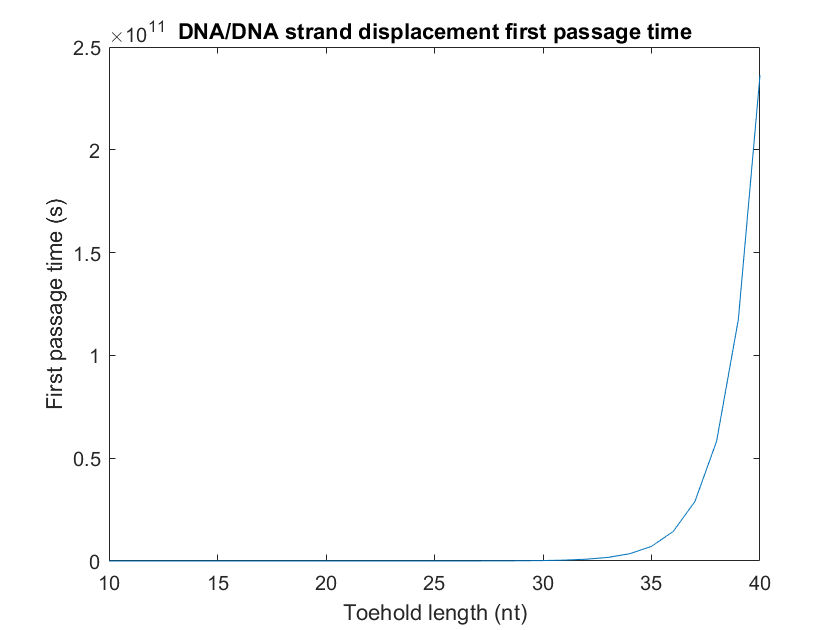

plot(10:40, first_pass_time)
ylabel('First passage time (s)')
xlabel('Toehold length (nt)')
title('DNA/DNA strand displacement first passage time')

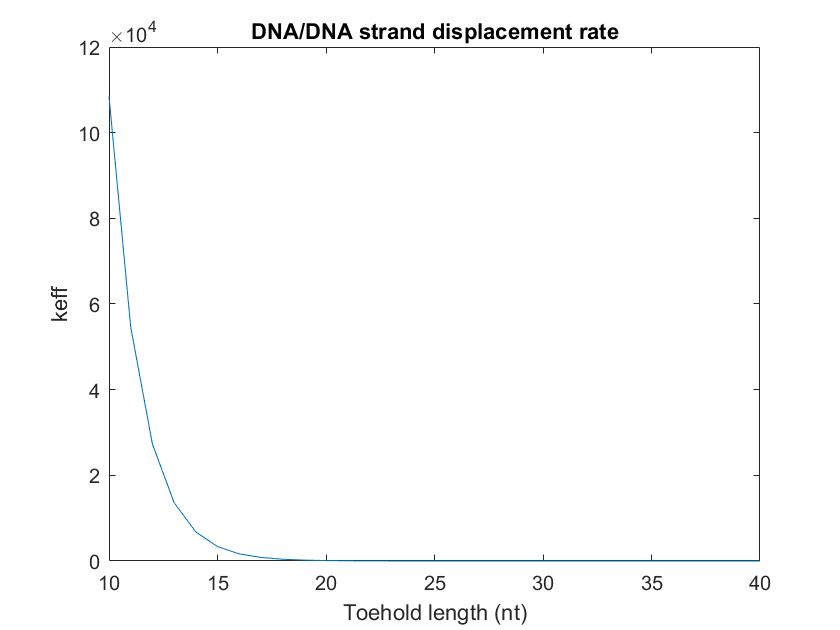


plot(10:40, k_eff)
xlabel('Toehold length (nt)')
ylabel('keff')
title('DNA/DNA strand displacement rate')

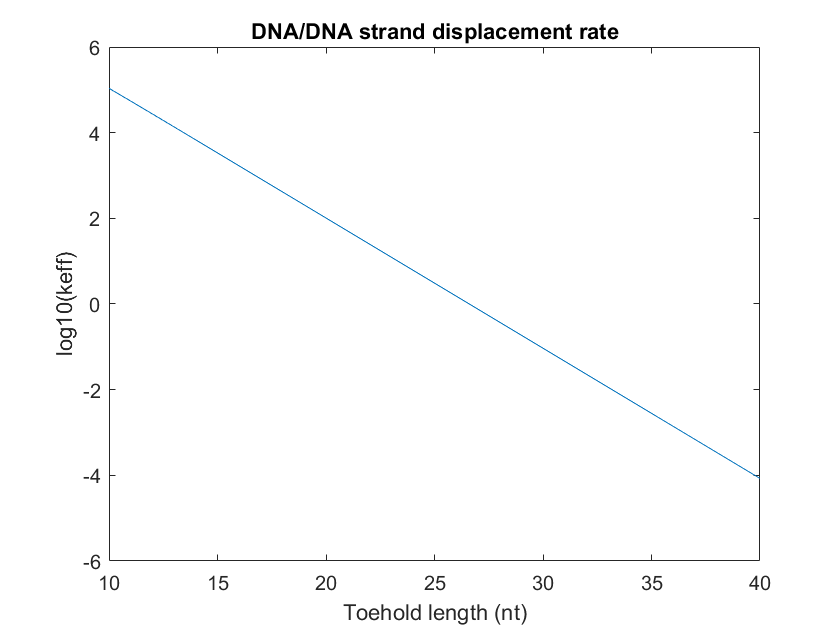


plot(10:40, log10(k_eff))
xlabel('Toehold length (nt)')
ylabel('log10(keff)')
title('DNA/DNA strand displacement rate')  